# Project 4 by Connor Nguyen UHid: 1787501

## Part 1

### P1.1

M = 200

dt = 5.0000e-04

CFL = 0.4805

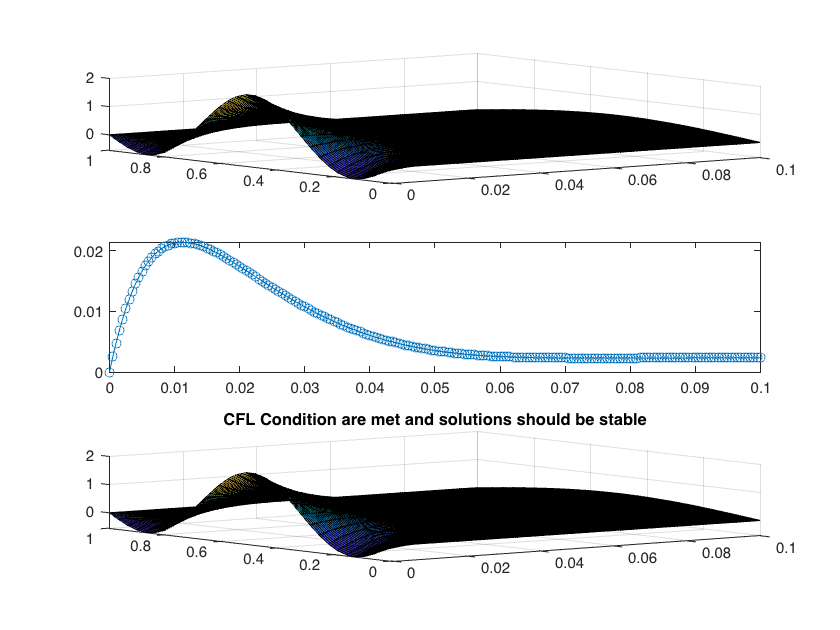

M = 50

dt = 0.0020

CFL = 1.9220

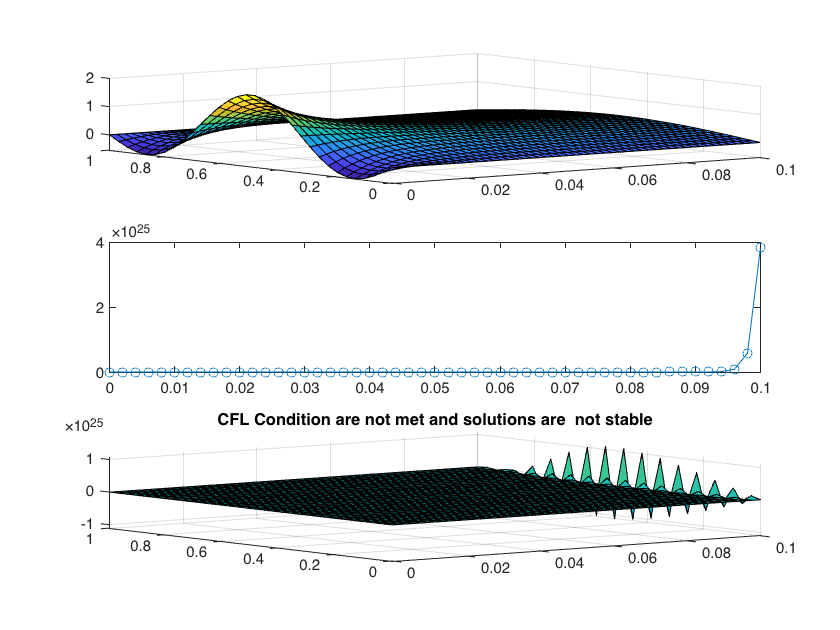

clear all;close all;

%Part 1a: The Diffusion Equation
%
%   ut= uxx
%   u(t,0)= u(t,1)= 0
%   u(0,x)= g(x)
%
% dx= 1/(N+1)
% u_t= Tdx*u ~ u^(m+1)= u^m + delta_t*Tdx*u^m <--- This is the Explicit Euler Form
%

% Exact solution

ga = @(x) sin(pi*x) - sin(3*pi*x);
ua = @(x,t) exp(-(pi)^2*t)*sin(pi*x) - exp(-(3*pi)^2*t)*sin(3*pi*x);

% Spatial Finite Difference Discretization

N = 30;
dx = 1/(N+1); % equidistance grid on [0,1] with N+1 subintervals

T = diag(-2*ones(N,1),0) + diag(ones(N-1,1),-1 )+ diag(ones(N-1,1),1);
Tdx = 1/(dx^2)*T;


xx= linspace(0,1,N+2); % equidistance grid on [0,1] with N+1 points

xx = xx';

% Temporal Euler Explicit 

tend = 0.1;

Mg = [200, 50];

for i = 1:length(Mg)

M = Mg(i)
dt = tend/M % total M time stepping
tt= linspace(0,tend,M+1); % time instants

Z= zeros(N+2,M+1); % soution u(x_i,t_m)

Za = zeros(N+2,M+1); % exact solution
err = zeros(M+1,1);

Z(:,1)= ga(xx); % initial condition u(x_i,0) = g(x_i)
Za(:,1) = ua(xx,tt(1));


err(1) = norm(Za(:,1)-Z(:,1));

for m = 1:M

  Z(:,m+1) = eulerstep(Tdx,Z(:,m),dt); % explicit Euler
  Za(:,m+1) = ua(xx,tt(m+1));
  err(m+1) = norm(Za(:,m+1)-Z(:,m+1));
end 

figure(i)

[T,X]= meshgrid(tt,xx);

subplot(3,1,1)
surf(T,X,Za) % This is the 3D plot of the exact solution

subplot(3,1,2)
plot(tt,err,'o-') % This is the 2D plot of the errors between the exact solution and computed ones.

subplot(3,1,3)
surf(T,X,Z) %This is going to give us the 3D plot

CFL = dt/dx^2

nrm0 = norm(Z(:,M));
nrm1 = norm(Z(:,M+1));

if (CFL < 1/2) 
  title('CFL Condition are met and solutions should be stable')
elseif (CFL>1/2 & nrm1<nrm0)
  title('CFL Condition are not met and solutions are  stable')
elseif (CFL>1/2 & nrm1>nrm0)
  title('CFL Condition are not met and solutions are  not stable')
end



end

## part 1.2


clear all;close all;

%Part 1.2: Solving the Diffusion Equation by the Crank-Nicolson Method
%
%   ut= uxx
%   u(t,0)= u(t,1)= 0
%   u(0,x)= g(x)
%

% Spatial Finite Difference Discretization

N = 30;
dx = 1/(N+1);

T = diag(-2*ones(N,1),0) + diag(ones(N-1,1),-1 )+ diag(ones(N-1,1),1);
Tdx = 1/(dx^2)*T;

%ga = @(x) sin(pi*x).^3;
ga = @(x) sin(pi*x) - sin(3*pi*x);
ua = @(x,t) exp(-(pi)^2*t)*sin(pi*x) - exp(-(3*pi)^2*t)*sin(3*pi*x);

xx= linspace(0,1,N+2);
xx = xx';

% Temporal grid

tend = 0.1;

Mg = [40];
for i = 1:length(Mg)

M = Mg(i);
dt = tend/M;
tt= linspace(0,tend,M+1);

Z= zeros(N+2,M+1);
Z(:,1)= ga(xx);

Za = zeros(N+2,M+1); % exact solution
Za(:,1) = ua(xx,tt(1));

err = zeros(M+1,1);
err(1) = norm(Za(:,1)-Z(:,1));

for m = 1:M

  Z(:,m+1) = TRstep(Tdx,Z(:,m),dt); % Crank-Nicolson method

  Za(:,m+1) = ua(xx,tt(m+1));
  err(m+1) = norm(Za(:,m+1)-Z(:,m+1));

end 

figure(i)
[T,X]= meshgrid(tt,xx);

subplot(3,1,1)
surf(T,X,Za) % This is the 3D plot of the exact solution

subplot(3,1,2)
plot(tt,err,'o-') % This is the 2D plot of the errors between the exact solution and computed ones.

subplot(3,1,3)
surf(T,X,Z) %This is going to give us the 3D plot
title('Crank-Nicolson Method and solutions should be stable')

end

## part 2

% The linear advection equation
%
%   ut+a*ux= 0
%
%   u(t,0)= u(t,1), u(0,x)= g(x)  x=0 and x=1
%   g(0)= g(1) and g'(0)= g'(1)
%   delta_x= 1/N
%
%   Lax-Wendroff scheme:
%
%   uj^(n+1)= a*mu/2(1+a*mu)u(j-1)^n + (1-a^2mu^2)uj^n -
%   a*mu/2(1-a*mu)u(j+1)^n

clear all;close all;


ga = @(x) exp(-100*(x-0.5).^2);

% Spatial Finite Difference Discretization

N= 30;
dx= 1/N;    % equidistance grid on [0,1] with N subintervals
xx= linspace(0,1,N+1); % equidistance grid on [0,1] with N points

M= 30;
tend = 5;   % time steps on [0,5]
dt = tend/M % total M time stepping

dt = 0.1667

tt= linspace(0,tend,M+1); % time instants

%a = 0.5
%amu = a*dt/dx;

amu = 0.9;
a= amu*dx/dt

a = 0.1800

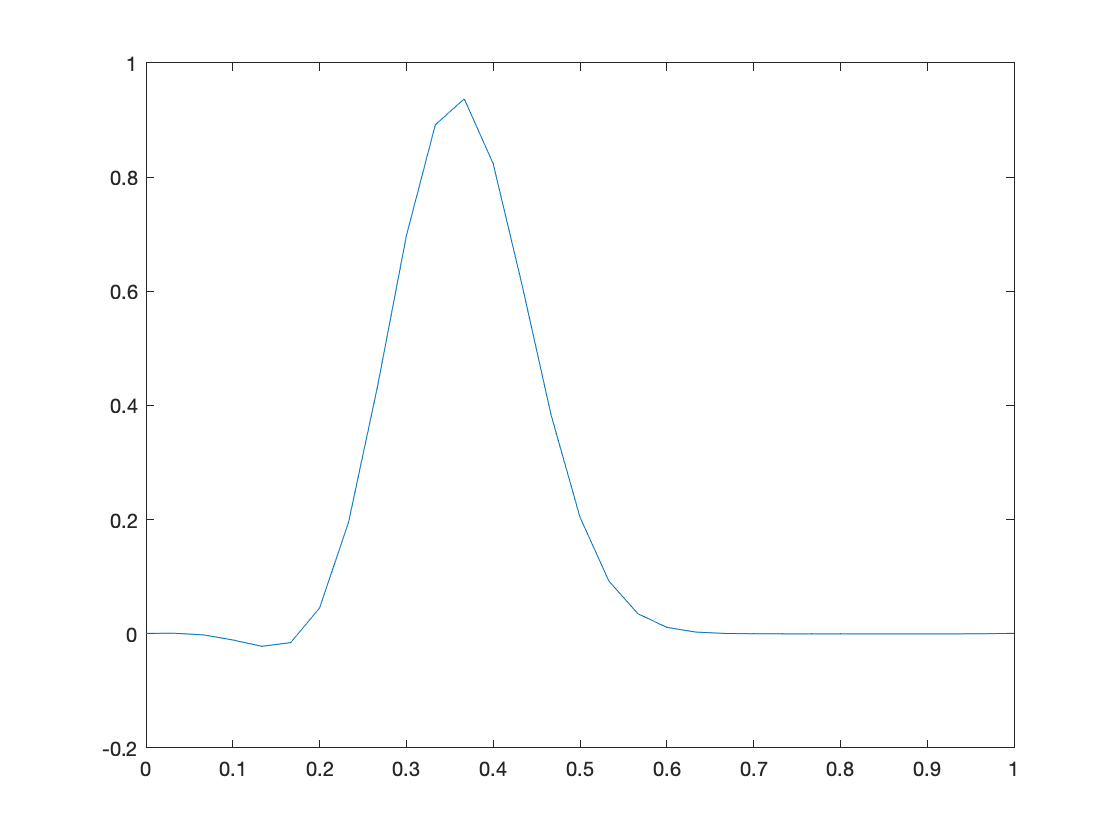


beta = amu/2*(amu+1); alpha = -amu^2; gamma = amu/2*(amu-1);

Tlw = diag(alpha*ones(N,1),0) + diag(beta*ones(N-1,1),-1 )+ diag(gamma*ones(N-1,1),1);
Tlw(1,N) = beta;
Tlw(N,1) = gamma;

% Temporal Lax-Wendroff

[T,X]= meshgrid(tt,xx);

Z= zeros(N+1,M+1); % soution u(x_i,t_m)
Z(:,1)= ga(xx); % initial condition u(x_i,0) = g(x_i)

% Create and open the video object
figure(1)
vidObj = VideoWriter('AdvectionMovie.avi');
open(vidObj);

for m = 1:M
 Z(:,m+1) = LaxWen(Tlw,Z(:,m)); % Lax-Wendroff solver
 
 % movies
 plot(xx,Z(:,m))

% store the frame
% Get the current frame
  currFrame = getframe;
%
% Write the current frame
  writeVideo(vidObj,currFrame);
end 


% M(i) = getframe(gcf);
% Close (and save) the video object
close(vidObj);

figure(2)
surf(T,X,Z);
title('amu= 1')


figure(3)
plot(Z)

format compact

CFL = dt/dx

CFL = 5

## Function

function unew= eulerstep(Tdx,uold,dt)

  N = length(uold);
  unew = zeros(N,1);
  unew(2:N-1) = uold(2:N-1) + dt*Tdx*uold(2:N-1);

end

function unew= LaxWen(Tlw,u)

    N = length(u);
    unew = zeros(N,1);
    unew(1:N-1) = u(1:N-1) + Tlw*u(1:N-1);
    unew(N) = unew(1);

end

function unew= TRstep(Tdx,uold,dt)

  N = length(uold);
  unew = zeros(N,1);
  unew(2:N-1) = (eye(N-2) - dt/2*Tdx)\(uold(2:N-1) + dt/2*Tdx*uold(2:N-1));

end